clf
dom = [0, 20];
N = chebop(@(t,u) diff(u,2)+pi.^2.*u-1, dom);
N.lbc = @(u) [u; diff(u)];

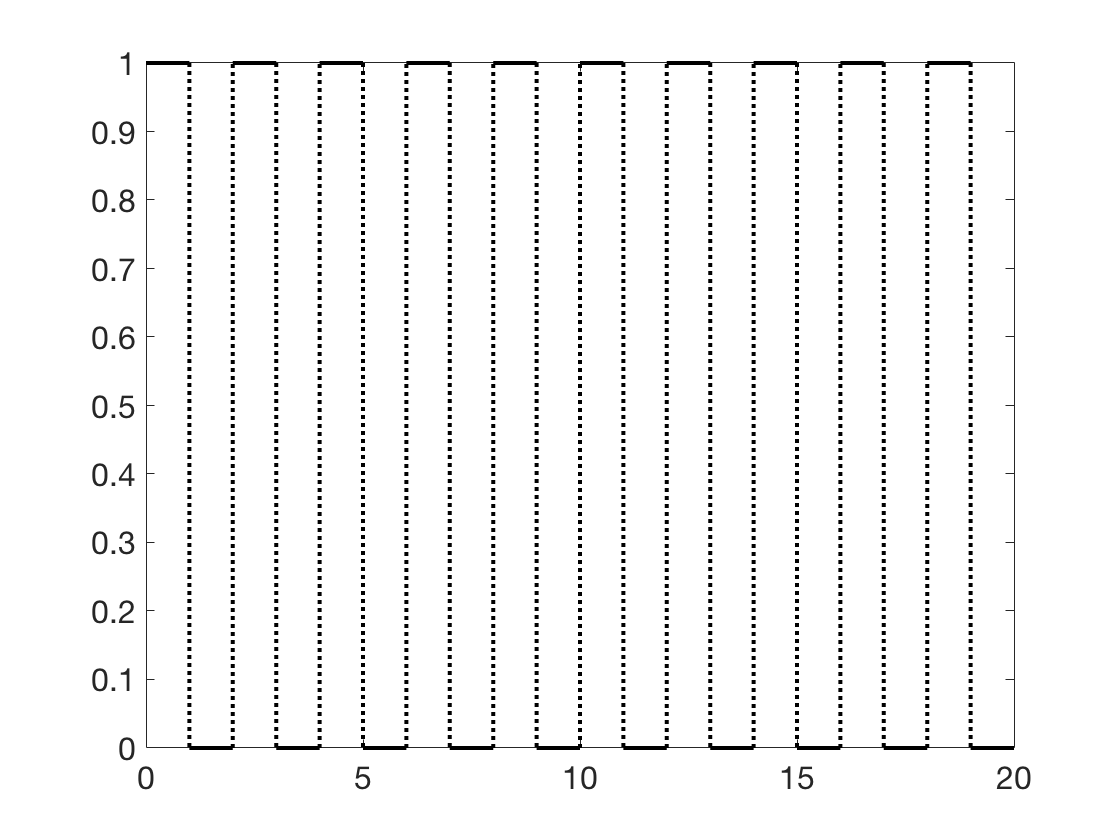

t = chebfun('t',[0 20]);
sq = (mod(t,2)<1);
clf, plot(sq,'k')

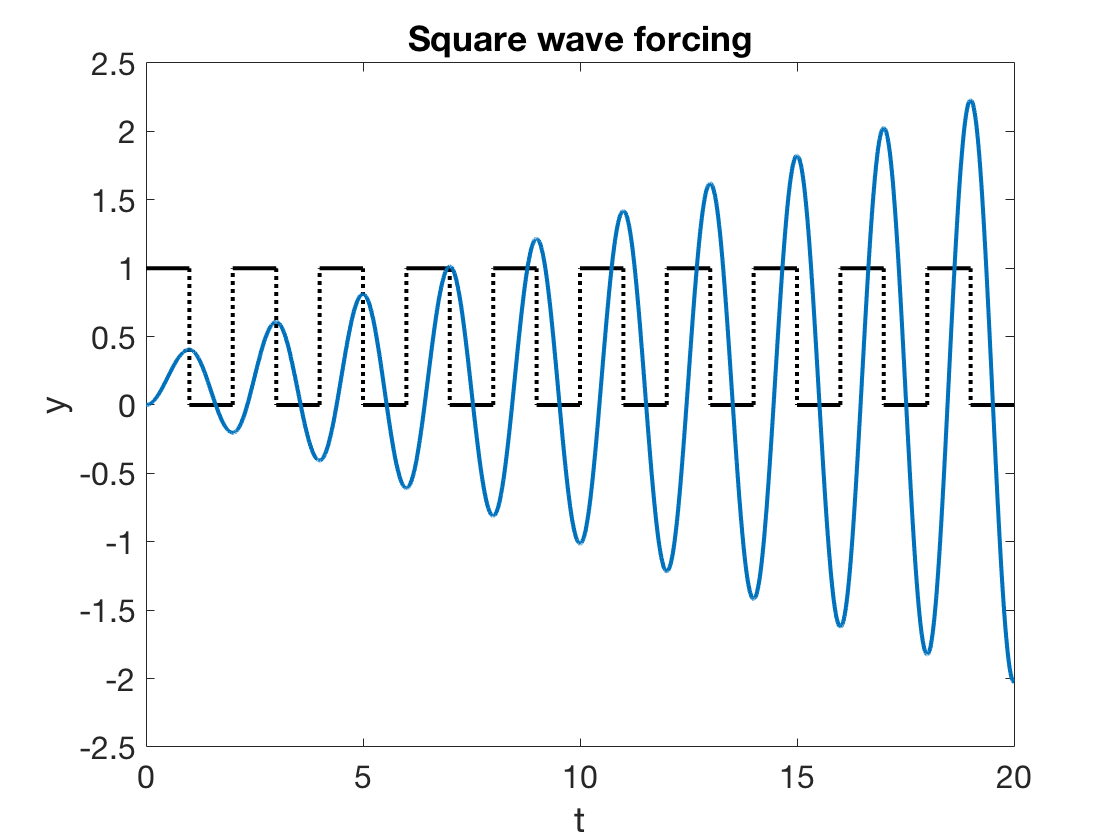

y = N\sq;
hold on, plot(y)
title('Square wave forcing'), xlabel('t'), ylabel('y')